clc; clear all; close all;

syms x t r
assume(x, 'real')

% Establish the function
fx = 1 + r*x + x^2;

% Compute the fixed points with respect to the control parameter 'r'
display('Possible Fixed Points:')

Possible Fixed Points:


Fpts = solve(fx, x);


% Determine the number of fixed points
n_fpts = length(Fpts);
display(['Maximum number of possible Fixed Points:', num2str(n_fpts)])

Maximum number of possible Fixed Points:2



% Save stable and unstable fixed points as well as r_trial
stable_Fpts = cell(1, 0);
unstable_Fpts = cell(1, 0);
r_stable = [];
r_unstable = [];
n_fpts_r = [];

% Loop over a range of 'r' values
r_values = -3:0.1:3

r_values =    -3.0000   -2.9000   -2.8000   -2.7000   -2.6000   -2.5000   -2.4000   -2.3000   -2.2000   -2.1000   -2.0000   -1.9000   -1.8000   -1.7000   -1.6000   -1.5000   -1.4000   -1.3000   -1.2000   -1.1000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000


for r_trial = r_values
    % Define the function for the current 'r'
    display(['Case of r trial = ', num2str(r_trial)])

    % Attempt to compute stability
    [stable, unstable] = Stability(fx, x, Fpts, r, r_trial);
    
    n_fpts_r = [n_fpts_r, length(stable) + length(unstable)];

    % Store the results, padding with NaN if necessary
    if ~isempty(unstable)
        unstable_Fpts{end+1} = double(subs(unstable, r, r_trial));
        r_unstable = [r_unstable, r_trial];
    end
    
    if ~isempty(stable)
        stable_Fpts{end+1} = double(subs(stable, r, r_trial));
        r_stable = [r_stable, r_trial];
    end
end

Case of r trial = -3


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.9


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.8


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.7


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.6


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.5


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.4


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.3


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.2


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2.1


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = -2


Only Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Case of r trial = -1.9


No Fixed Points


Case of r trial = -1.8


No Fixed Points


Case of r trial = -1.7


No Fixed Points


Case of r trial = -1.6


No Fixed Points


Case of r trial = -1.5


No Fixed Points


Case of r trial = -1.4


No Fixed Points


Case of r trial = -1.3


No Fixed Points


Case of r trial = -1.2


No Fixed Points


Case of r trial = -1.1


No Fixed Points


Case of r trial = -1


No Fixed Points


Case of r trial = -0.9


No Fixed Points


Case of r trial = -0.8


No Fixed Points


Case of r trial = -0.7


No Fixed Points


Case of r trial = -0.6


No Fixed Points


Case of r trial = -0.5


No Fixed Points


Case of r trial = -0.4


No Fixed Points


Case of r trial = -0.3


No Fixed Points


Case of r trial = -0.2


No Fixed Points


Case of r trial = -0.1


No Fixed Points


Case of r trial = 0


No Fixed Points


Case of r trial = 0.1


No Fixed Points


Case of r trial = 0.2


No Fixed Points


Case of r trial = 0.3


No Fixed Points


Case of r trial = 0.4


No Fixed Points


Case of r trial = 0.5


No Fixed Points


Case of r trial = 0.6


No Fixed Points


Case of r trial = 0.7


No Fixed Points


Case of r trial = 0.8


No Fixed Points


Case of r trial = 0.9


No Fixed Points


Case of r trial = 1


No Fixed Points


Case of r trial = 1.1


No Fixed Points


Case of r trial = 1.2


No Fixed Points


Case of r trial = 1.3


No Fixed Points


Case of r trial = 1.4


No Fixed Points


Case of r trial = 1.5


No Fixed Points


Case of r trial = 1.6


No Fixed Points


Case of r trial = 1.7


No Fixed Points


Case of r trial = 1.8


No Fixed Points


Case of r trial = 1.9


No Fixed Points


Case of r trial = 2


Only Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Case of r trial = 2.1


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.2


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.3


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.4


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.5


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.6


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.7


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.8


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 2.9


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

Case of r trial = 3


Stable Fixed Points:


$$-\frac{r}{2}-\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}$$

Unstable Fixed Points:


$$\frac{\sqrt{\left(r-2\right)\,\left(r+2\right)}}{2}-\frac{r}{2}$$

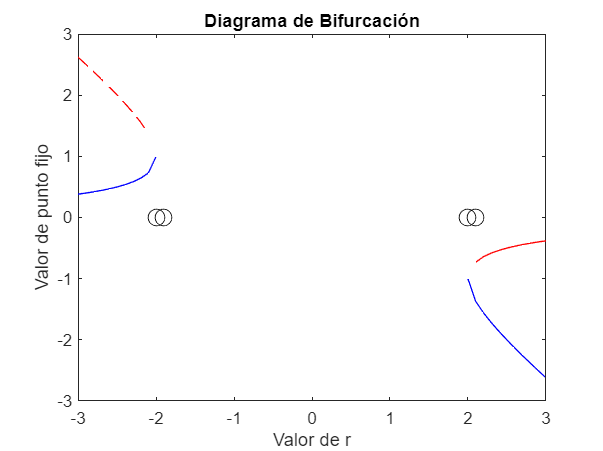


% Inicializa una lista para almacenar los puntos de bifurcación
puntos_de_bifurcacion = [];

% Compara los elementos consecutivos en n_fpts_r
% Compara los elementos consecutivos en n_fpts_r
for i = 2:length(n_fpts_r)
    if n_fpts_r(i) ~= n_fpts_r(i - 1)
        % Ha habido un cambio en el número de fixed points, lo que indica una bifurcación
        % Almacena el valor de r en el que se produce la bifurcación
        puntos_de_bifurcacion = [puntos_de_bifurcacion, r_values(i)];
    end
end

% Plot del diagrama de bifurcación
% Supongamos que tienes las listas de puntos de bifurcación, r_stable, r_unstable,
% y las celdas de puntos fijos stable_Fpts y unstable_Fpts

% Inicializa una figura
figure;

% Agrega un punto de bifurcación ficticio al final de la lista de puntos de bifurcación
% para asegurarte de que se procesen todos los segmentos


% Itera sobre los puntos de bifurcación
for i = 1:length(puntos_de_bifurcacion) - 1
    % Define los límites del segmento actual
    limite_inferior = puntos_de_bifurcacion(i);
    limite_superior = puntos_de_bifurcacion(i + 1);
    
    % Filtra los valores de r, r_stable y r_unstable por debajo del límite inferior
    r_stable_inf = r_stable(r_stable < limite_inferior);
    r_unstable_inf = r_unstable(r_unstable < limite_inferior);
    
    % Extrae los puntos fijos correspondientes al segmento actual
    stable_Fpts_inf = [];
    unstable_Fpts_inf = [];
    indice_stable_inf = [];
    indice_unstable_inf = [];
    if ~isempty(r_stable_inf)
        % Encuentra el índice del segmento actual en las celdas
        for k = 1:length(r_stable_inf)
            indice_stable_inf = [indice_stable_inf, find(r_stable==r_stable_inf(k))];
        end
        stable_Fpts_inf = [stable_Fpts_inf, stable_Fpts{indice_stable_inf}];
        plot(r_stable_inf, stable_Fpts_inf, 'b-');
        hold on
    end
    if ~isempty(r_unstable_inf)
        for k = 1:length(r_unstable_inf)
            indice_unstable_inf = [indice_unstable_inf, find(r_stable==r_stable_inf(k))];
        end
        unstable_Fpts_inf = [unstable_Fpts_inf, unstable_Fpts{indice_unstable_inf}];
        plot(r_unstable_inf, unstable_Fpts_inf, 'r--');
        hold on
    end

    % Filtra los valores de r, r_stable y r_unstable entre los límites
    r_stable_bet = r_stable(r_stable >= limite_inferior & r_stable <= limite_superior + 1e-10);
    r_unstable_bet = r_unstable(r_unstable >= limite_inferior & r_unstable <= limite_superior);

    % Extrae los puntos fijos correspondientes al segmento actual
    stable_Fpts_bet = [];
    unstable_Fpts_bet = [];
    indice_stable_bet = [];
    indice_unstable_bet = [];
    if ~isempty(r_stable_bet)
        % Encuentra el índice del segmento actual en las celdas
        for k = 1:length(r_stable_bet)
            indice_stable_bet = [indice_stable_bet, find(r_stable==r_stable_bet(k))];
        end
        stable_Fpts_bet = [stable_Fpts_bet, stable_Fpts{indice_stable_bet}];
        plot(r_stable_bet, stable_Fpts_bet, 'b-');
        hold on
    end
    if ~isempty(r_unstable_bet)
        for k = 1:length(r_unstable_bet)
            indice_unstable_bet = [indice_unstable_bet, find(r_unstable==r_unstable_bet(k))];
        end
        unstable_Fpts_bet = [unstable_Fpts_bet, unstable_Fpts{indice_unstable_bet}];
        plot(r_unstable_bet, unstable_Fpts_bet, 'r--');
        hold on
    end


    % Filtra los valores de r, r_stable y r_unstable por encima del límite superior
    r_stable_sup = r_stable(r_stable > limite_superior);
    r_unstable_sup = r_unstable(r_unstable > limite_superior);
    
    % Extrae los puntos fijos correspondientes al segmento actual
    stable_Fpts_sup = [];
    unstable_Fpts_sup = [];
    indice_stable_sup = [];
    indice_unstable_sup = [];
    if ~isempty(r_stable_sup)
        % Encuentra el índice del segmento actual en las celdas
        for k = 1:length(r_stable_sup)
            indice_stable_sup = [indice_stable_sup, find(r_stable==r_stable_sup(k))];
        end
        stable_Fpts_sup = [stable_Fpts_sup, stable_Fpts{indice_stable_sup}];
        plot(r_stable_sup, stable_Fpts_sup, 'b-');
        hold on
    end
    if ~isempty(r_unstable_sup)
        for k = 1:length(r_unstable_sup)
            indice_unstable_sup = [indice_unstable_sup, find(r_unstable==r_unstable_sup(k))];
        end
        unstable_Fpts_sup = [unstable_Fpts_sup, unstable_Fpts{indice_unstable_sup}];
        plot(r_unstable_sup, unstable_Fpts_sup, 'r--');
        hold on
    end
    
    % Traza los puntos de bifurcación en el segmento
    plot(puntos_de_bifurcacion, 0, 'ko', 'MarkerSize', 10);
    
    % Traza los puntos fijos para r_stable en el segmento
    %plot(r_stable_segmento, stable_Fpts_segmento, 'b.', 'MarkerSize', 10);
    
    % Traza los puntos fijos para r_unstable en el segmento
    %plot(r_unstable_segmento, unstable_Fpts_segmento, 'r.', 'MarkerSize', 10);
    
    hold on
end

% Añade etiquetas y título
xlabel('Valor de r');
ylabel('Valor de punto fijo');
title('Diagrama de Bifurcación');


% Establece la leyenda
%legend('Punto de Bifurcación', 'Puntos Fijos Estables', 'Puntos Fijos Inestables', 'Location', 'Best');*